# Intensity images from HDF5 file

It is easiet to run this live script  section by section one at a time

## Choose desired HDF5 file

addpath('Functions')


filename=uigetfile('*.h5');%try '20221202_09_21_23.h5';
DispComments(filename)

Transmission Data for SHG Fourier ptychography and bonus synthetic aperture. 10x10 scan path. Slide position: 11.38mm delay: 3.09mm. Trying again after adjusting reference alignment, This time longer dwell time. Narrower scan range: scan amplitude=.22/1.5V which is NA/Lambda/1.5. 


**Play video of Intensity images **

Transmission Data for SHG Fourier ptychography and bonus synthetic aperture. 10x10 scan path. Slide position: 11.38mm delay: 3.09mm. Trying again after adjusting reference alignment, This time longer dwell time. Narrower scan range: scan amplitude=.22/1.5V which is NA/Lambda/1.5. 


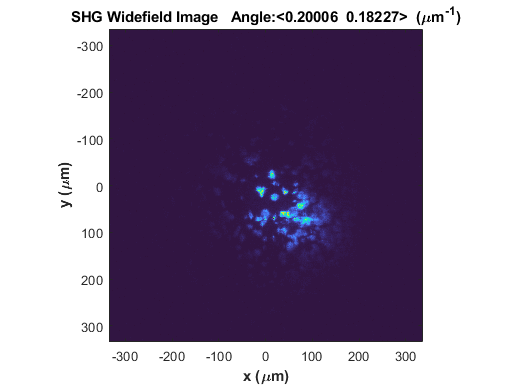

GenerateTransmissionSHGMovie(filename)

### **Now retrive Intensity images from HDF5 file into 3D array. Also output set of vectors describing the shift in each spectrum: **$\langle f_x,  f_y \rangle$ in units of $\mu m^{-1}$


[IntMat tilts]=IntensityStack(filename);

Random Illumination data in transmission with thick BaTiO3 sample. Ground fused silica diffuser taped to slide with ground side facing out (toward the illumination objective) 21*21 points scanned about 1/1.5 the NA. This time adjusting reference to be more centered. Added a thin film diffuser in between the glass diffuser and the sample to ensure Illumination is random and un correlated. SHorter exposure time
